clc; clear; close all;

load('w_normalized.mat')



rows = size(w_normalized, 1);
columns = size(w_normalized, 2);
figure;
[XI, ETA] = meshgrid(1:columns, 1:rows);

figure;
surf(XI, ETA, w_normalized)

dw_normalized = diff(w_normalized)
[XI_prime, ETA_prime] = meshgrid(1:columns, 1:rows-1);
figure;
scatter3(XI_prime(:), ETA_prime(:), dw_normalized(:))


d = 7;
C = 27;
n_r = 6;

M = d+3;

h_tan = 0.0005;
h_mesh = 0.00025;

if(exist(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']) == 0 | ...
   exist(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']) == 0)
    disp('FC data not found. Generating FC operators... \n');
    generate_bdry_continuations(d, C, C, 12, 20, 4, ...
        256, n_r);
end

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']);

A = double(A);
Q = double(Q);

fcont = fcont_gram_blend_S(w_normalized, d, A, Q);
rows_fcont = size(fcont, 1);
columns_fcont = size(fcont, 2);
[XI_fcont, ETA_fcont] = meshgrid(1:columns_fcont, 1:rows_fcont);
figure;
surf(XI_fcont, ETA_fcont, fcont)
xlabel('xi');
ylabel('eta');

xi_idx = 84;

figure;
scatter(ETA(:, xi_idx), w_normalized(:, xi_idx))
fcont_1D = fcont_gram_blend_S(w_normalized(:, xi_idx), d, A, Q);

figure;
plot(w_normalized(:, 80:85));

fcont_1D = fcont_gram_blend_S(w_normalized(:, 80:85), d, A, Q);
plot(fcont_1D)

plot(diff(w_normalized(:, 80:85), 1, 1))

polyfit(transpose(1:7), w_normalized(:, xi_idx), 6)

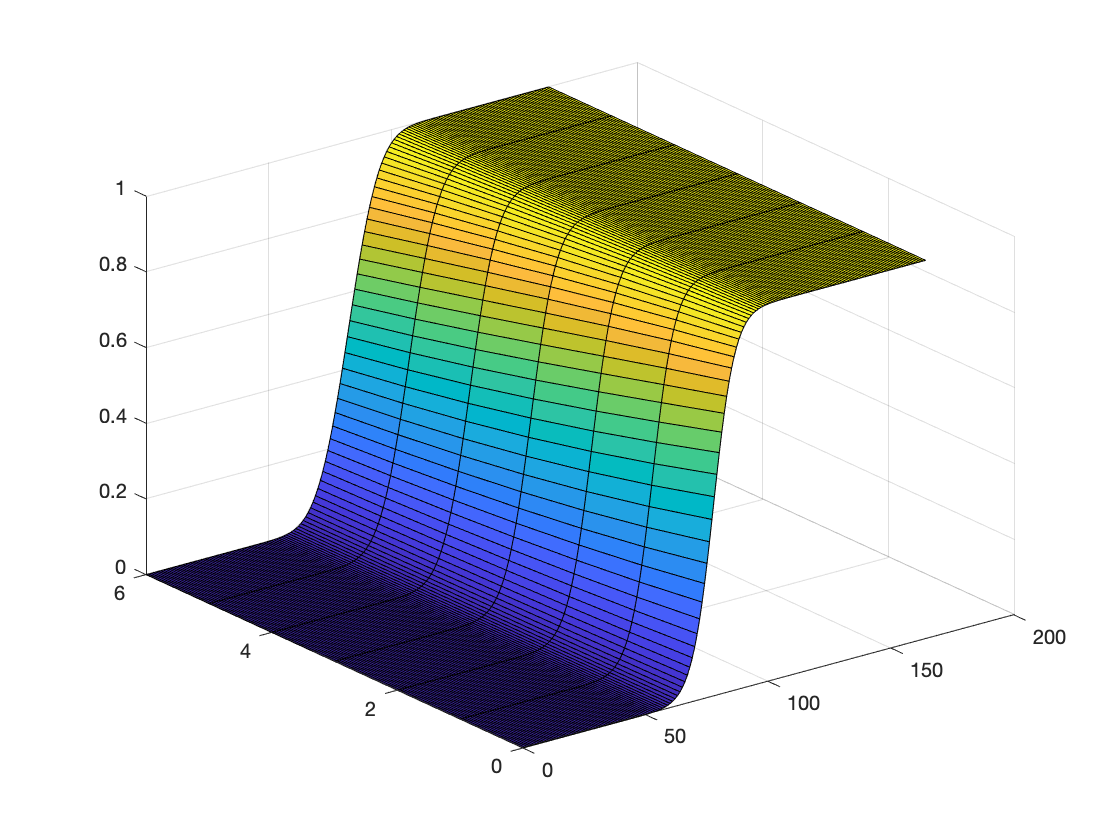

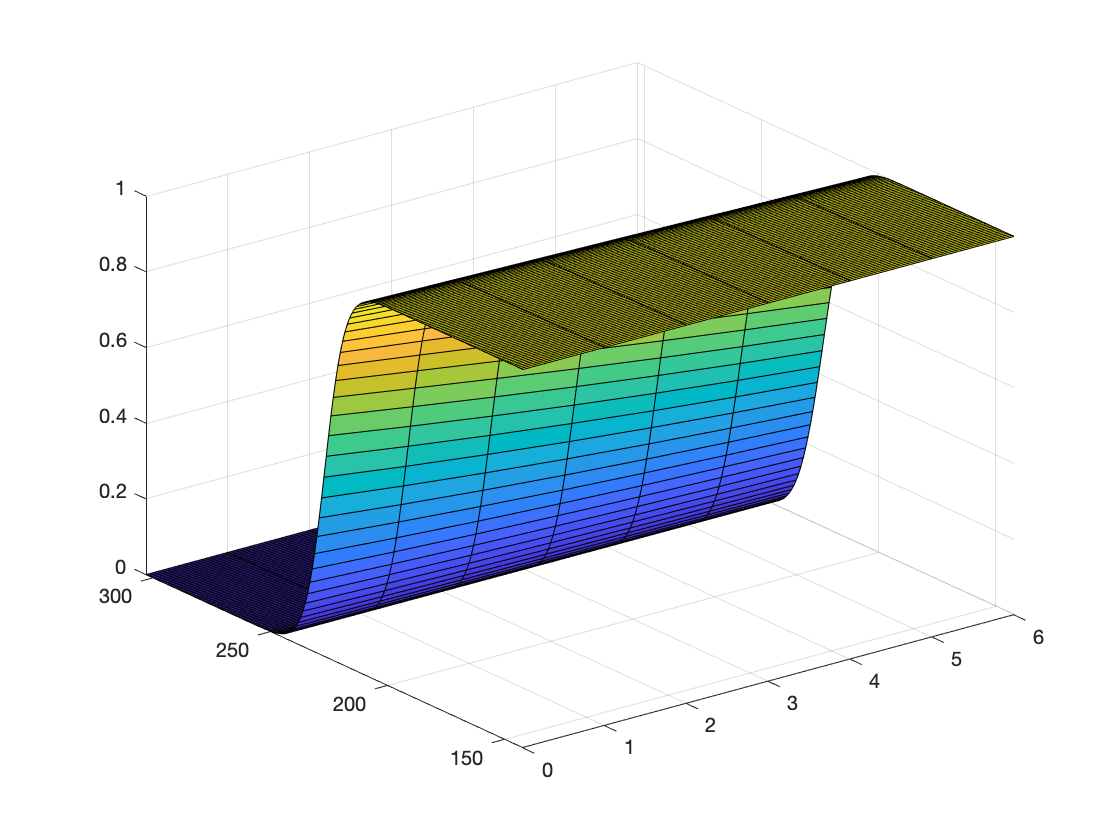

clc; clear; close all;

load('patches.mat')

C_patch = patches{2};
S_patch = patches{3};

C_patch.apply_w_L(S_patch)

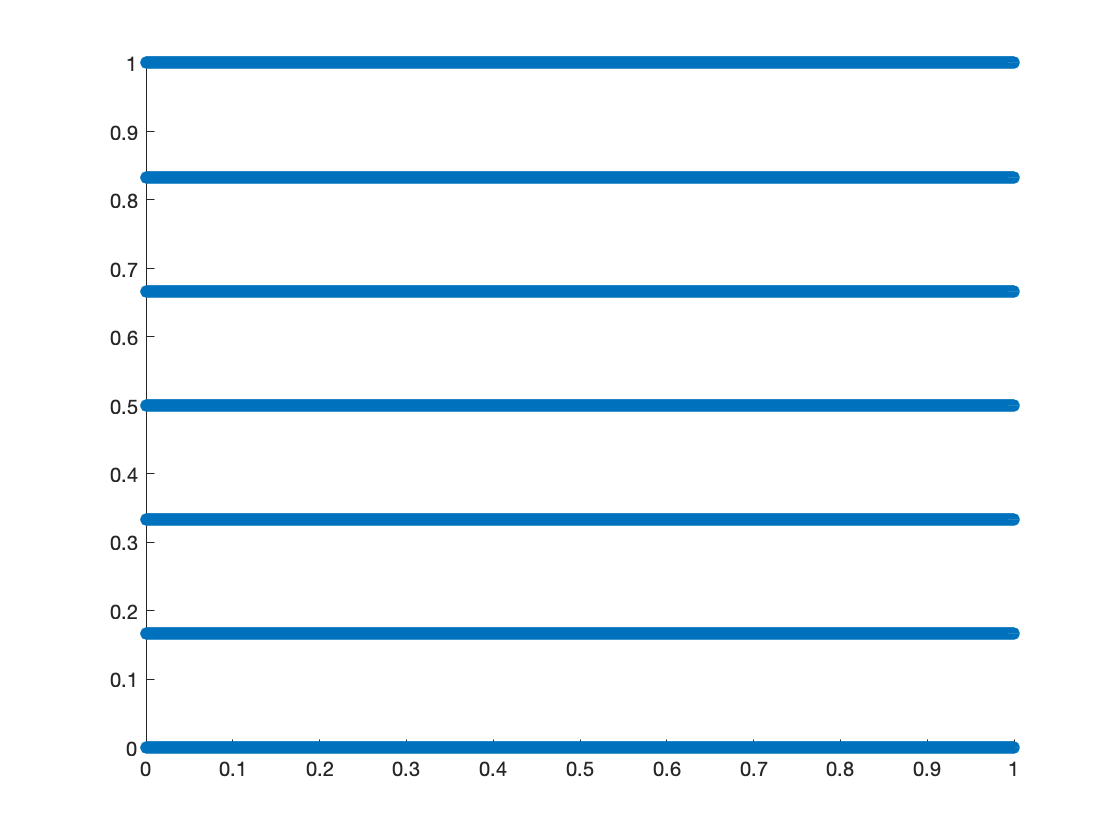


figure;
[XI, ETA] = S_patch.Q.xi_eta_mesh;
scatter(XI(:), ETA(:))


[h_xi_S, h_eta_S] = S_patch.Q.h_mesh;
[h_xi_C, h_eta_C] = C_patch.L.h_mesh;

window_eta = C_patch.L.eta_end

window_eta = 1

window_xi = C_patch.L.xi_start

window_xi = 0


main_xi_corner = S_patch.Q.xi_start;


while true
    window_xy = C_patch.L.M_p(window_xi, window_eta)
    [main_xi, main_eta, converged] = S_patch.Q.inverse_M_p(window_xy(1), window_xy(2), nan)
    if (main_xi > main_xi_corner)
        main_xi_corner = main_xi;
    end
    if main_eta > S_patch.Q.eta_end || main_eta < S_patch.Q.eta_start
        break;
    end
    window_xi = window_xi + h_xi_C;
end

window_xy =     0.0998    0.0010


main_xi = 0.0553

main_eta = 0

converged = logical
   1


window_xy =     0.1002    0.0013


main_xi = 0.0557

main_eta = 0.1142

converged = logical
   1


window_xy =     0.1005    0.0017


main_xi = 0.0561

main_eta = 0.2285

converged = logical
   1


window_xy =     0.1009    0.0021


main_xi = 0.0565

main_eta = 0.3426

converged = logical
   1


window_xy =     0.1012    0.0024


main_xi = 0.0569

main_eta = 0.4568

converged = logical
   1


window_xy =     0.1016    0.0028


main_xi = 0.0573

main_eta = 0.5709

converged = logical
   1


window_xy =     0.1019    0.0031


main_xi = 0.0577

main_eta = 0.6851

converged = logical
   1


window_xy =     0.1023    0.0035


main_xi = 0.0581

main_eta = 0.7991

converged = logical
   1


window_xy =     0.1026    0.0038


main_xi = 0.0585

main_eta = 0.9132

converged = logical
   1


window_xy =     0.1030    0.0042


main_xi = 0.0589

main_eta = 1.0272

converged = logical
   1


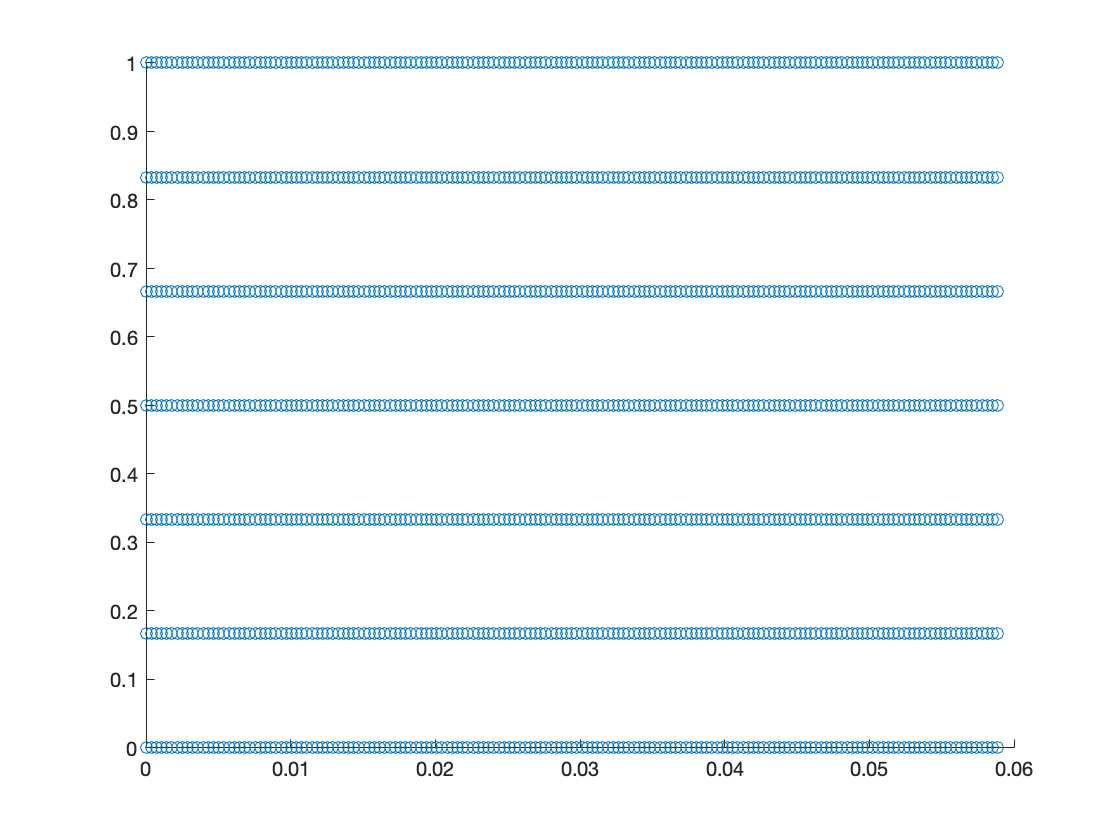


[XI_overlap, ETA_overlap, XI_j, ETA_j] = compute_xi_overlap_mesh(S_patch.Q, main_xi_corner);


figure;
scatter(XI_overlap(:), ETA_overlap(:))

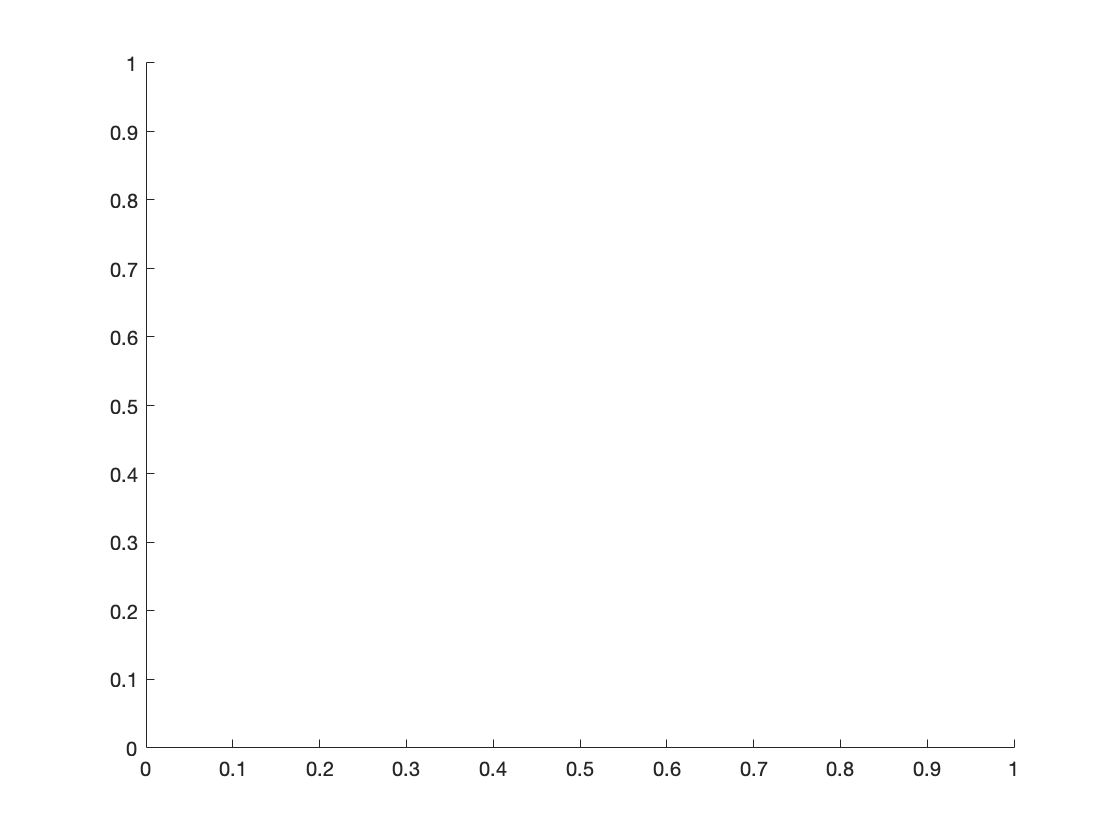


figure;
hold on;

s = surf(R.R_X, R.R_Y, R.f_R);

Unable to resolve the name R.R_X.

s.EdgeColor = 'none'
hold on;

for i = 1:8
    [X, Y] = fc_patches{i}.xy_mesh;
    scatter(X(:), Y(:))
end

curve_seq.last_curve.n_S_1

ans = 345


figure;
[X, Y] = fc_patches{5}.xy_mesh;
X_overlap = X(:, end-curve_seq.last_curve.n_S_1+1:end);
Y_overlap = Y(:, end-curve_seq.last_curve.n_S_1+1:end);

f_S_overlap = fc_patches{5}.f_XY(end, end-curve_seq.last_curve.n_S_1+1:end)

f_S_overlap =     2.7863    2.7773    2.7682    2.7592    2.7502    2.7412    2.7321    2.7231    2.7141    2.7051    2.6960    2.6870    2.6780    2.6689    2.6599    2.6509    2.6418    2.6328    2.6238    2.6147    2.6057    2.5967    2.5876    2.5786    2.5696    2.5606    2.5515    2.5425    2.5335    2.5245    2.5155    2.5065    2.4975    2.4884    2.4794    2.4705    2.4615    2.4525    2.4435    2.4345    2.4255    2.4166    2.4076    2.3987    2.3897    2.3808    2.3718    2.3629    2.3540    2.3451


scatter(X_overlap(:), Y_overlap(:))

f_exact = f(X_overlap(end, :), Y_overlap(end, :))

f_exact =     2.7863    2.7773    2.7682    2.7592    2.7502    2.7412    2.7321    2.7231    2.7141    2.7051    2.6960    2.6870    2.6780    2.6689    2.6599    2.6509    2.6418    2.6328    2.6238    2.6147    2.6057    2.5967    2.5876    2.5786    2.5696    2.5606    2.5515    2.5425    2.5335    2.5245    2.5155    2.5065    2.4975    2.4884    2.4794    2.4705    2.4615    2.4525    2.4435    2.4345    2.4255    2.4166    2.4076    2.3987    2.3897    2.3808    2.3718    2.3629    2.3540    2.3451


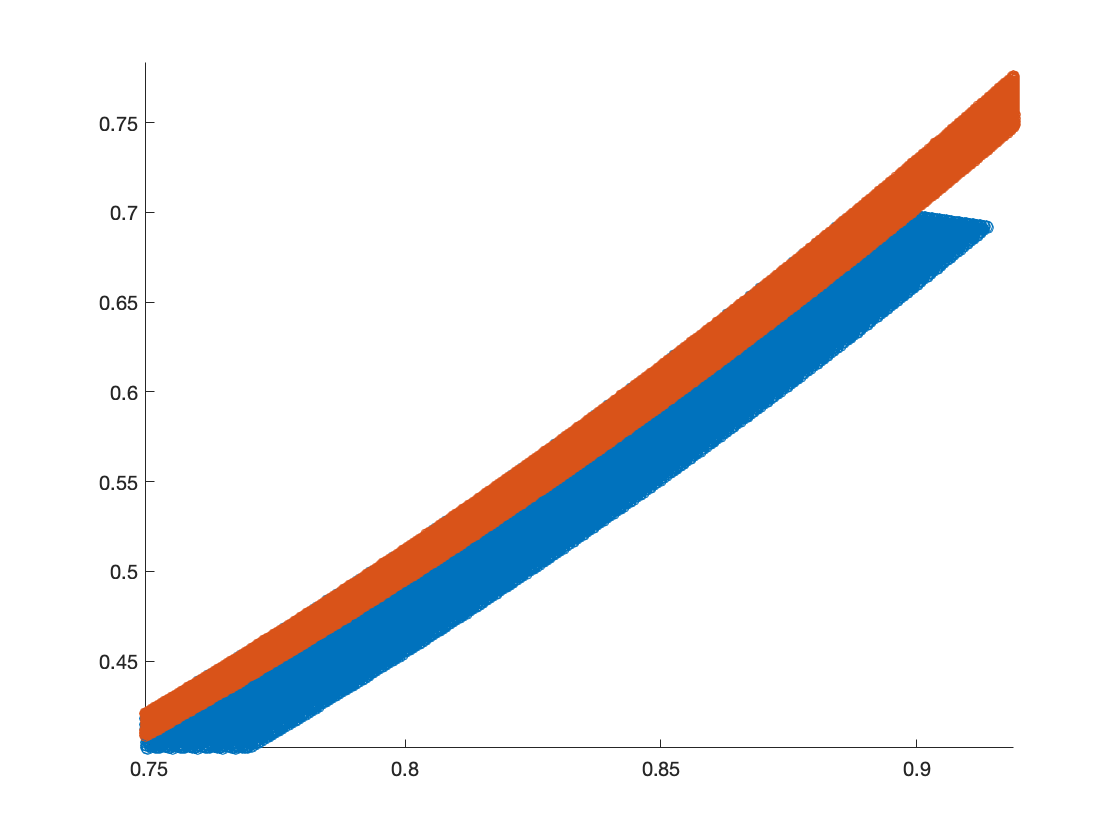

hold on;
[X, Y] = fc_patches{7}.xy_mesh;
X_overlap = X(:, end-curve_seq.last_curve.n_S_1+1:end);
Y_overlap = Y(:, end-curve_seq.last_curve.n_S_1+1:end);
scatter(X(:), Y(:))

f_C_overlap = fliplr(fc_patches{7}.f_XY(end, end-curve_seq.last_curve.n_S_1+1:end))

f_C_overlap =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



curve_seq.first_curve.n_S_1

ans = 315


max(abs(f_exact-f_S_overlap-f_C_overlap))

ans = 5.7732e-15

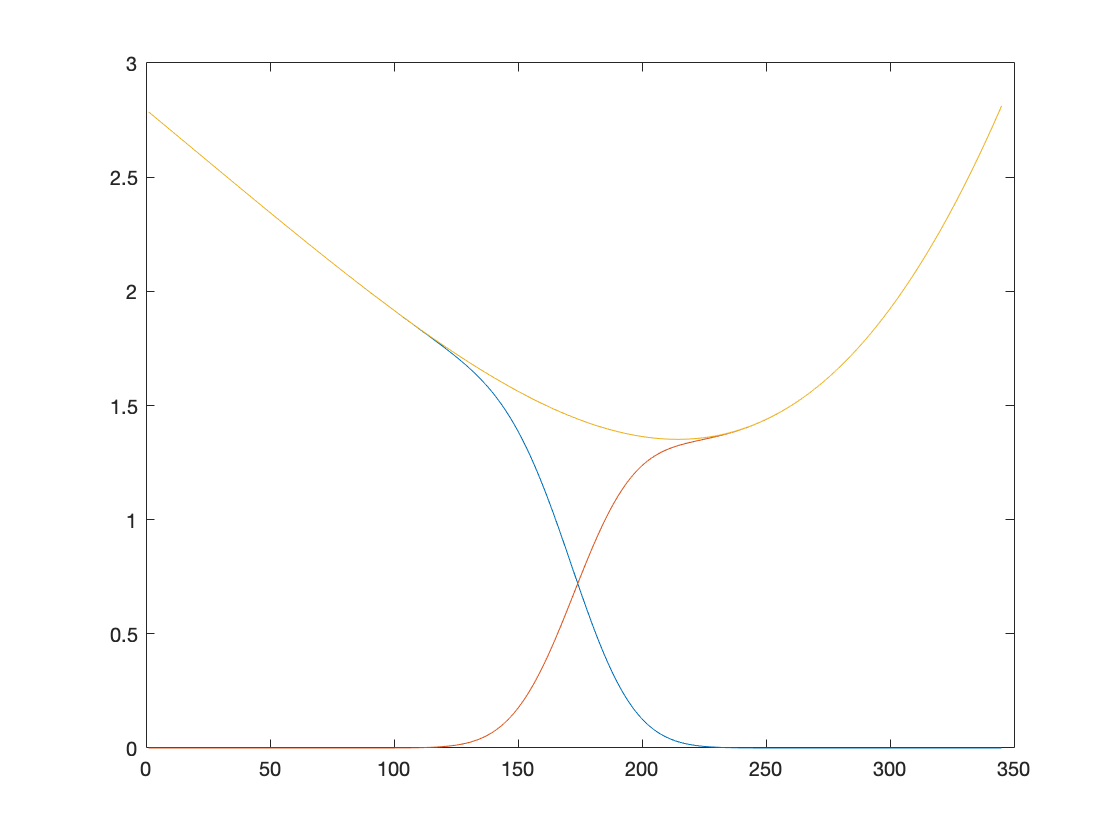


figure;
plot(f_S_overlap)
hold on;
plot(f_C_overlap)
plot(f_exact)

curve_seq.first_curve

ans =   Curve_obj with properties:

           l_1: @(theta)-theta+1
           l_2: @(theta)-theta+1
     l_1_prime: @(theta)-1*ones(size(theta))
     l_2_prime: @(theta)-1*ones(size(theta))
    l_1_dprime: @(theta)zeros(size(theta))
    l_2_dprime: @(theta)zeros(size(theta))
             n: 1416
         n_C_0: 472
         n_C_1: 472
         n_S_0: 315
         n_S_1: 315
         h_tan: 7.0671e-04
        h_norm: 1.0000e-03
    next_curve: [1×1 Curve_obj]


curve_seq.last_curve

ans =   Curve_obj with properties:

           l_1: @(theta)theta
           l_2: @(theta)theta.^3
     l_1_prime: @(theta)ones(size(theta))
     l_2_prime: @(theta)3*theta.^2
    l_1_dprime: @(theta)zeros(size(theta))
    l_2_dprime: @(theta)6*theta
             n: 1549
         n_C_0: 517
         n_C_1: 517
         n_S_0: 345
         n_S_1: 345
         h_tan: 6.4599e-04
        h_norm: 1.0000e-03
    next_curve: [1×1 Curve_obj]


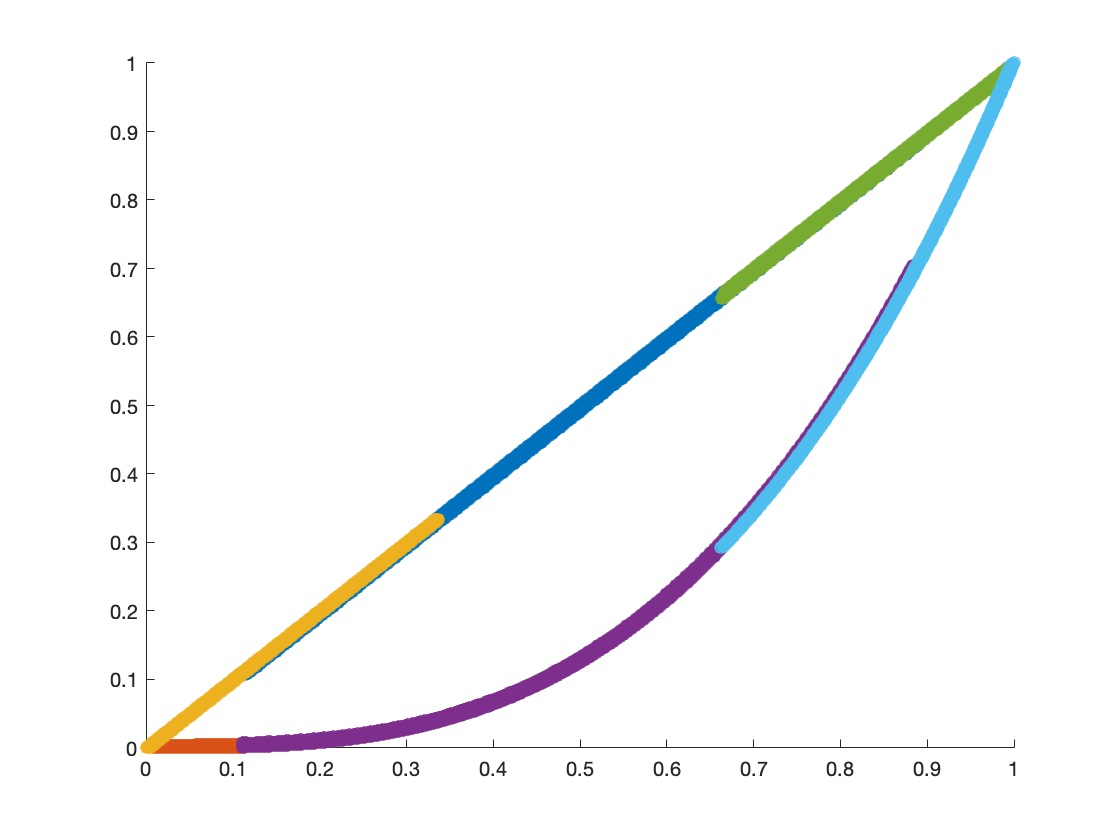

patches = 4×1 cell array
    {1×1 S_patch_obj }
    {1×1 C2_patch_obj}
    {1×1 S_patch_obj }
    {1×1 C2_patch_obj}


patches = curve_seq.construct_patches(f, d, 1e-13, 1e-13)

S_patch = patches{3}

S_patch =   S_patch_obj with properties:

              Q: [1×1 Q_patch_obj]
    M_p_general: @(xi,eta,H)[M_p_1_general(xi,eta,H),M_p_2_general(xi,eta,H)]
      J_general: @(v,H)[dM_p_1_dxi(v(1),v(2),H),dM_p_1_deta(v(1),v(2),H);dM_p_2_dxi(v(1),v(2),H),dM_p_2_deta(v(1),v(2),H)]
              h: 1.0000e-03


C_patch = patches{4}

C_patch =   C2_patch_obj with properties:

    L: [1×1 Q_patch_obj]
    W: [1×1 Q_patch_obj]



x_test = 0.814977;
y_test = 0.54189;

f_exact = f(x_test, y_test)

f_exact = 1.3663


[xi, eta] = C_patch.W.inverse_M_p(x_test, y_test, nan);
f_C = C_patch.W.locally_compute(xi, eta, d)

f_C = 1.3634


[xi, eta] = S_patch.Q.inverse_M_p(x_test, y_test, nan);
f_S = S_patch.Q.locally_compute(xi, eta, d)

f_S = 0.0029


f_exact - f_C - f_S

ans = -3.4326e-12

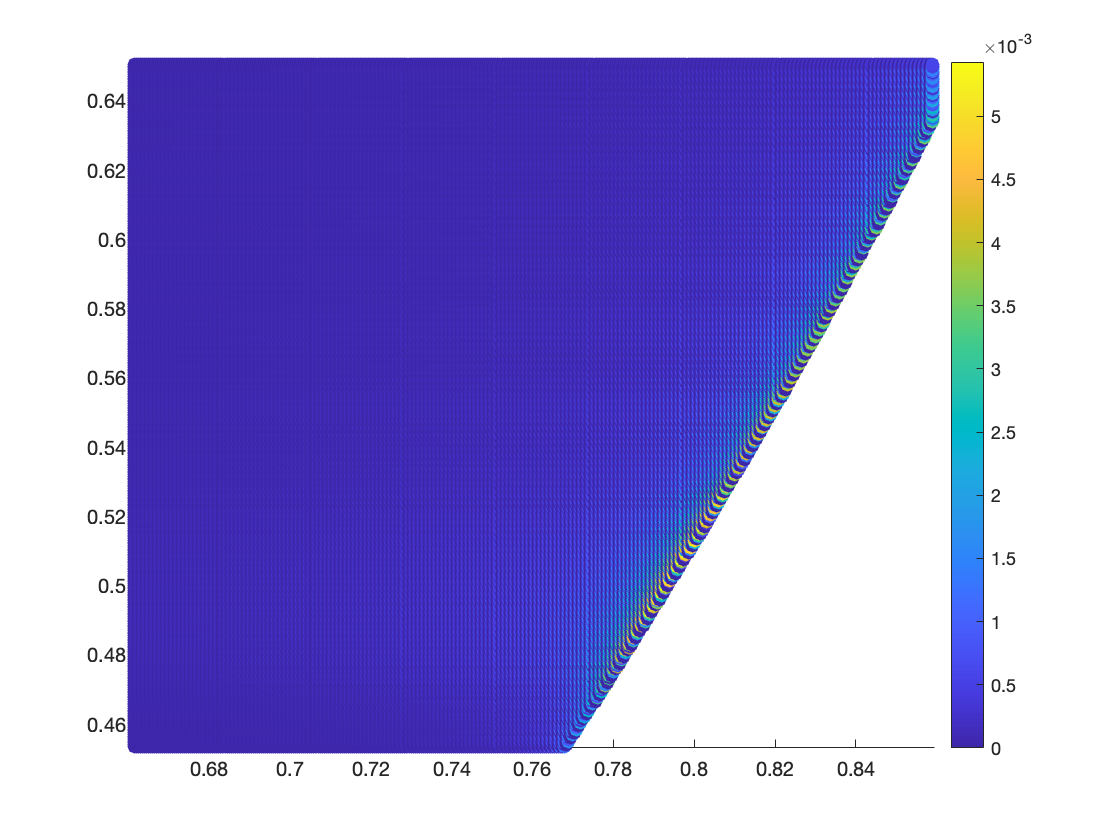


% figure;
% [R_X_err, R_Y_err, f_interpolation, interior_idx] = R.ifft_interpolation(h/2);
% f_exact = f(R_X_err, R_Y_err);
% err = abs(f_exact - f_interpolation);
% 
% scatter(R_X_err(interior_idx), R_Y_err(interior_idx), 50, err(interior_idx), 'filled') % 50 is the marker size, 'filled' makes the markers solid
% 
% % Add color bar to indicate the range of values
% colorbar

function [XI_overlap, ETA_overlap, XI_j, ETA_j] = compute_xi_overlap_mesh(main_patch, xi_corner)
%COMPUTE_XI_OVERLAP_MESH Summary of this function goes here
%   Detailed explanation goes here
    [h_xi, h_eta] = main_patch.h_mesh;
    
    xi_corner_j = floor((xi_corner - main_patch.xi_start) / h_xi);
    [XI_j, ETA_j] = meshgrid(0:xi_corner_j, 0:(main_patch.n_eta-1));
    
    XI_overlap = XI_j * h_xi + main_patch.xi_start;
    ETA_overlap = ETA_j * h_eta + main_patch.eta_start;
end